clc;
clear;
fullpath = 'C:\Users\rakyn\OneDrive\Desktop\TERM6\MISP_LAB\EOG_sig.mat';
load(fullpath)
size(Sig(1,:))

ans =            1        7680


**Q1:**

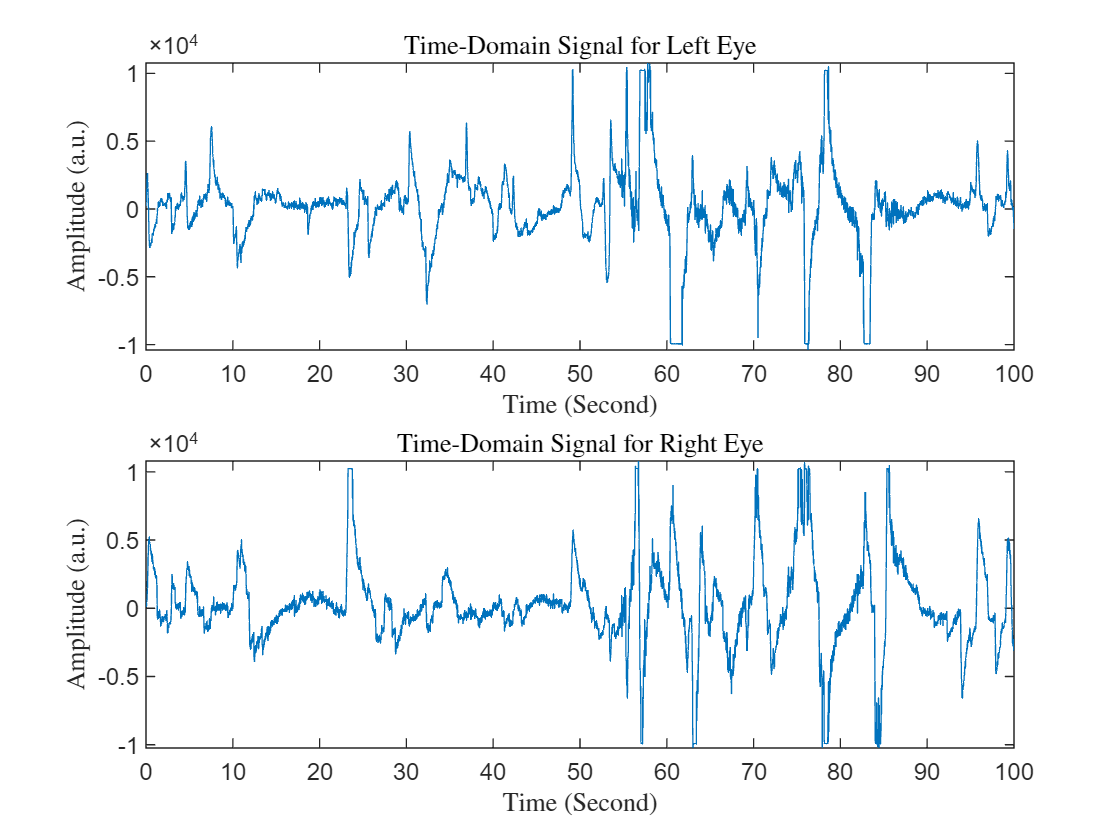

%%
time=linspace(0,100,7680);

figure; 
subplot(2,1,1);

plot(time,Sig(1,:));
xlabel('Time (Second)', Interpreter='latex');
ylabel('Amplitude (a.u.)', Interpreter='latex');
title('Time-Domain Signal for Left Eye', Interpreter='latex');

 subplot(2,1,2);
 plot(time, Sig(2,:));
 xlabel('Time (Second)', Interpreter='latex');
 ylabel('Amplitude (a.u.)', Interpreter='latex');
 title('Time-Domain Signal for Right Eye', Interpreter='latex');

**Q2:**

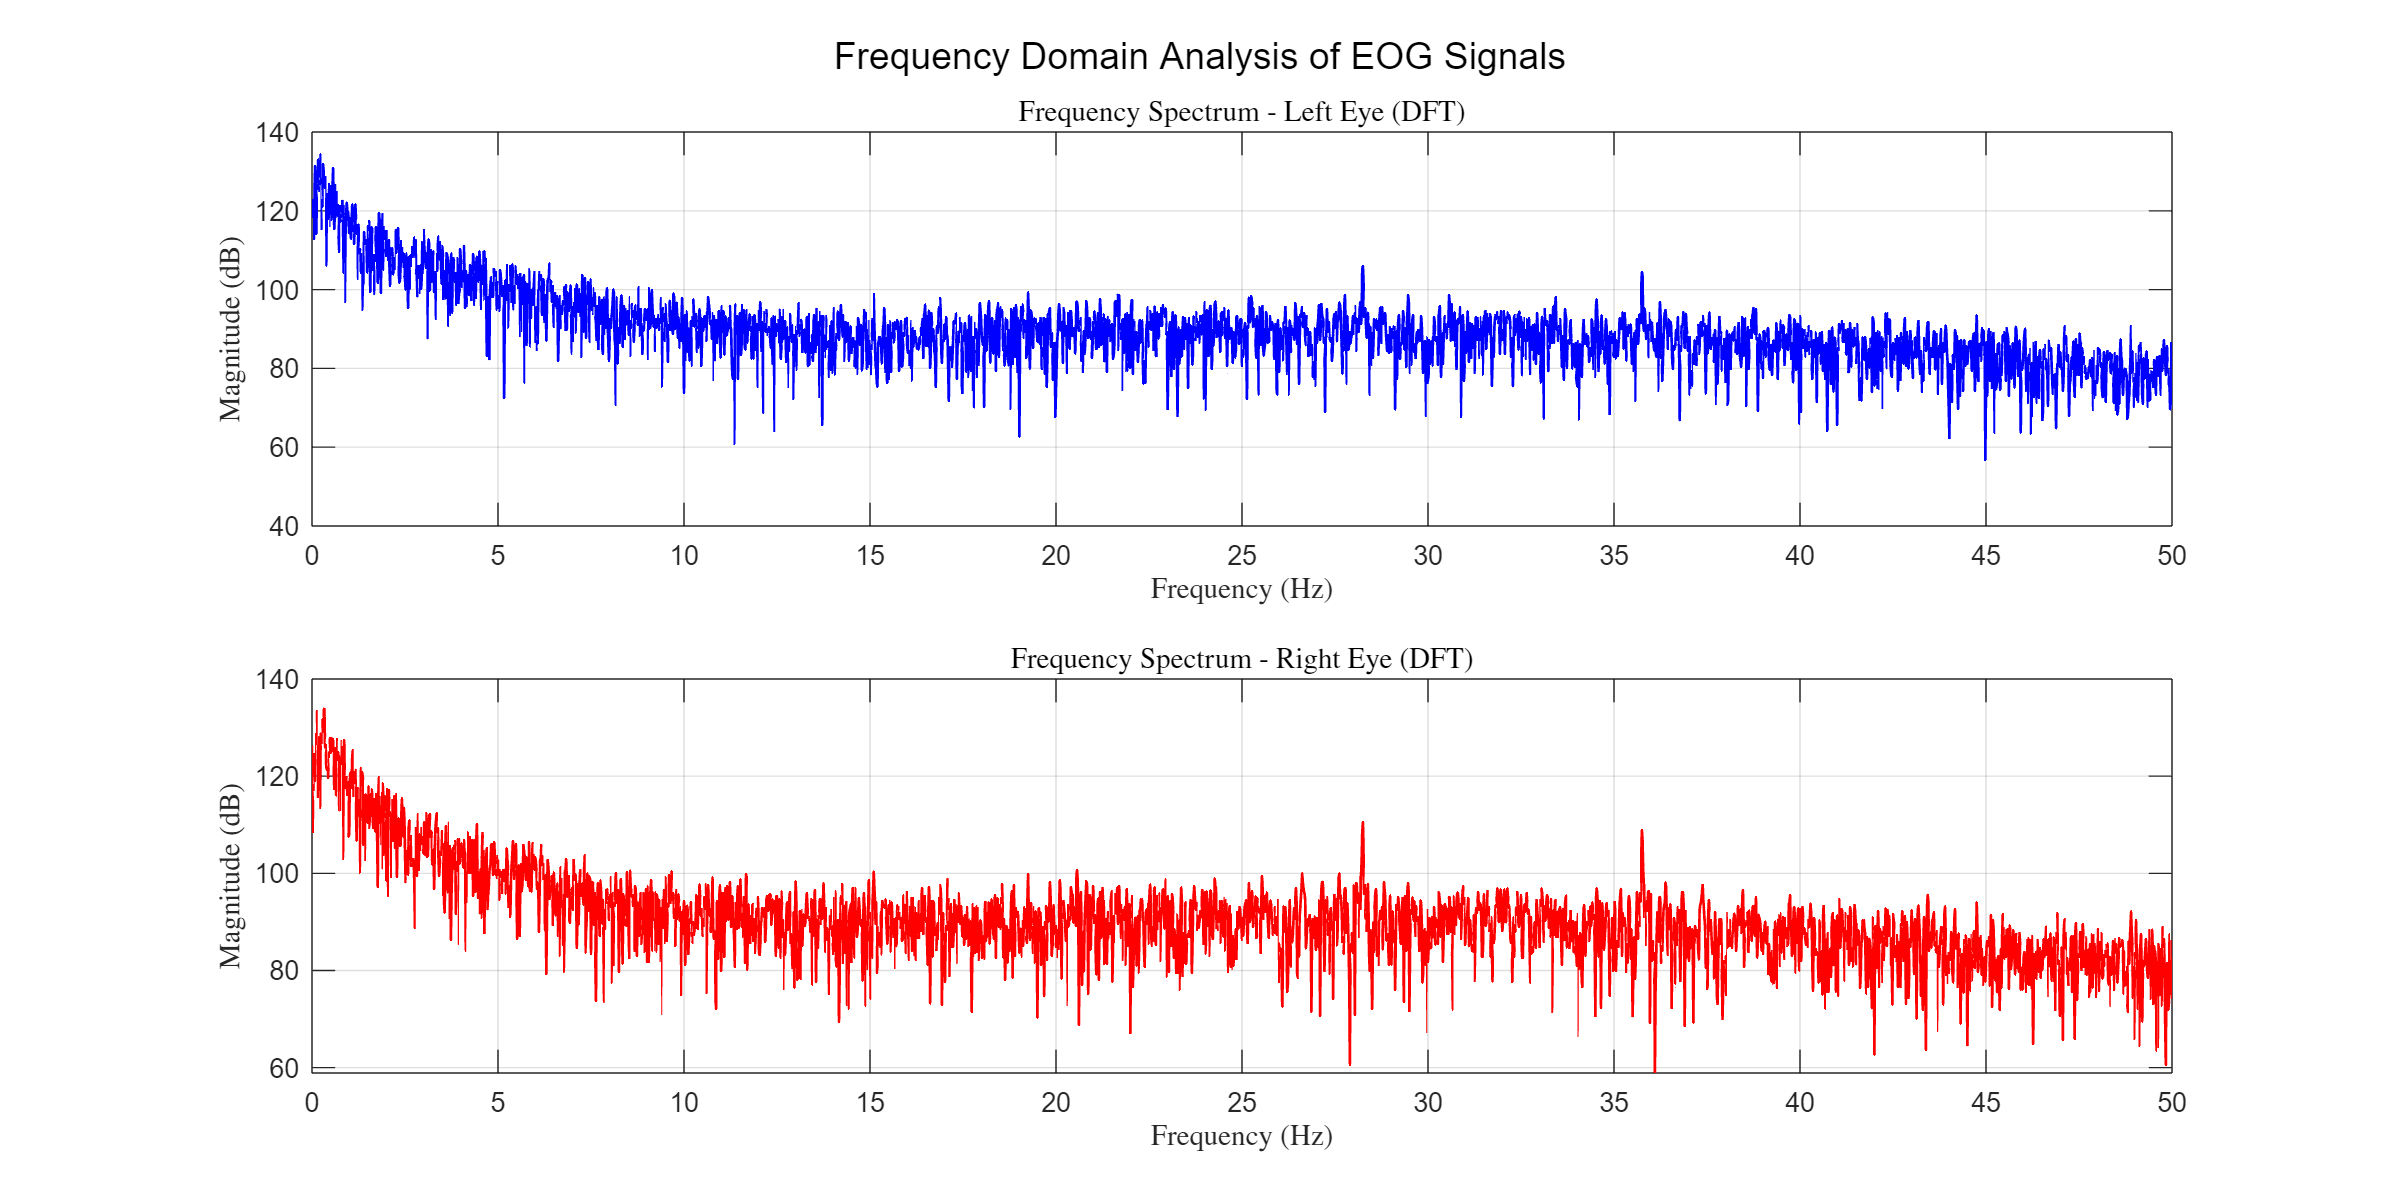

eog_left=Sig(1,:);
eog_right=Sig(2,:);

fft_signal_left=fft(eog_left);
N_left=length(eog_left);
freq_left=(0:(N_left-1))*fs/N_left;
freq_left=freq_left(1:floor(N_left/2));
fft_mag_left=20*log10(abs(fft_signal_left(1:floor(N_left/2)))+eps);

subplot(2,1,1);
plot(freq_left, fft_mag_left, 'b-', 'LineWidth', 1);
xlabel('Frequency (Hz)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Frequency Spectrum - Left Eye (DFT)', 'Interpreter', 'latex');
xlim([0, min(50, fs/2)]);
grid on;

N_right = length(eog_right);
fft_signal_right = fft(eog_right);
freq_right = (0:N_right-1) * (fs / N_right);
freq_right = freq_right(1:floor(N_right/2));

fft_mag_right_linear = abs(fft_signal_right(1:floor(N_right/2)));
fft_mag_right_dB = 20 * log10(fft_mag_right_linear + eps);

subplot(2,1,2);
plot(freq_right, fft_mag_right_dB, 'r-', 'LineWidth', 1);
xlabel('Frequency (Hz)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Frequency Spectrum - Right Eye (DFT)', 'Interpreter', 'latex');
xlim([0, min(50, fs/2)]);
grid on;

sgtitle('Frequency Domain Analysis of EOG Signals', 'FontSize', 14);

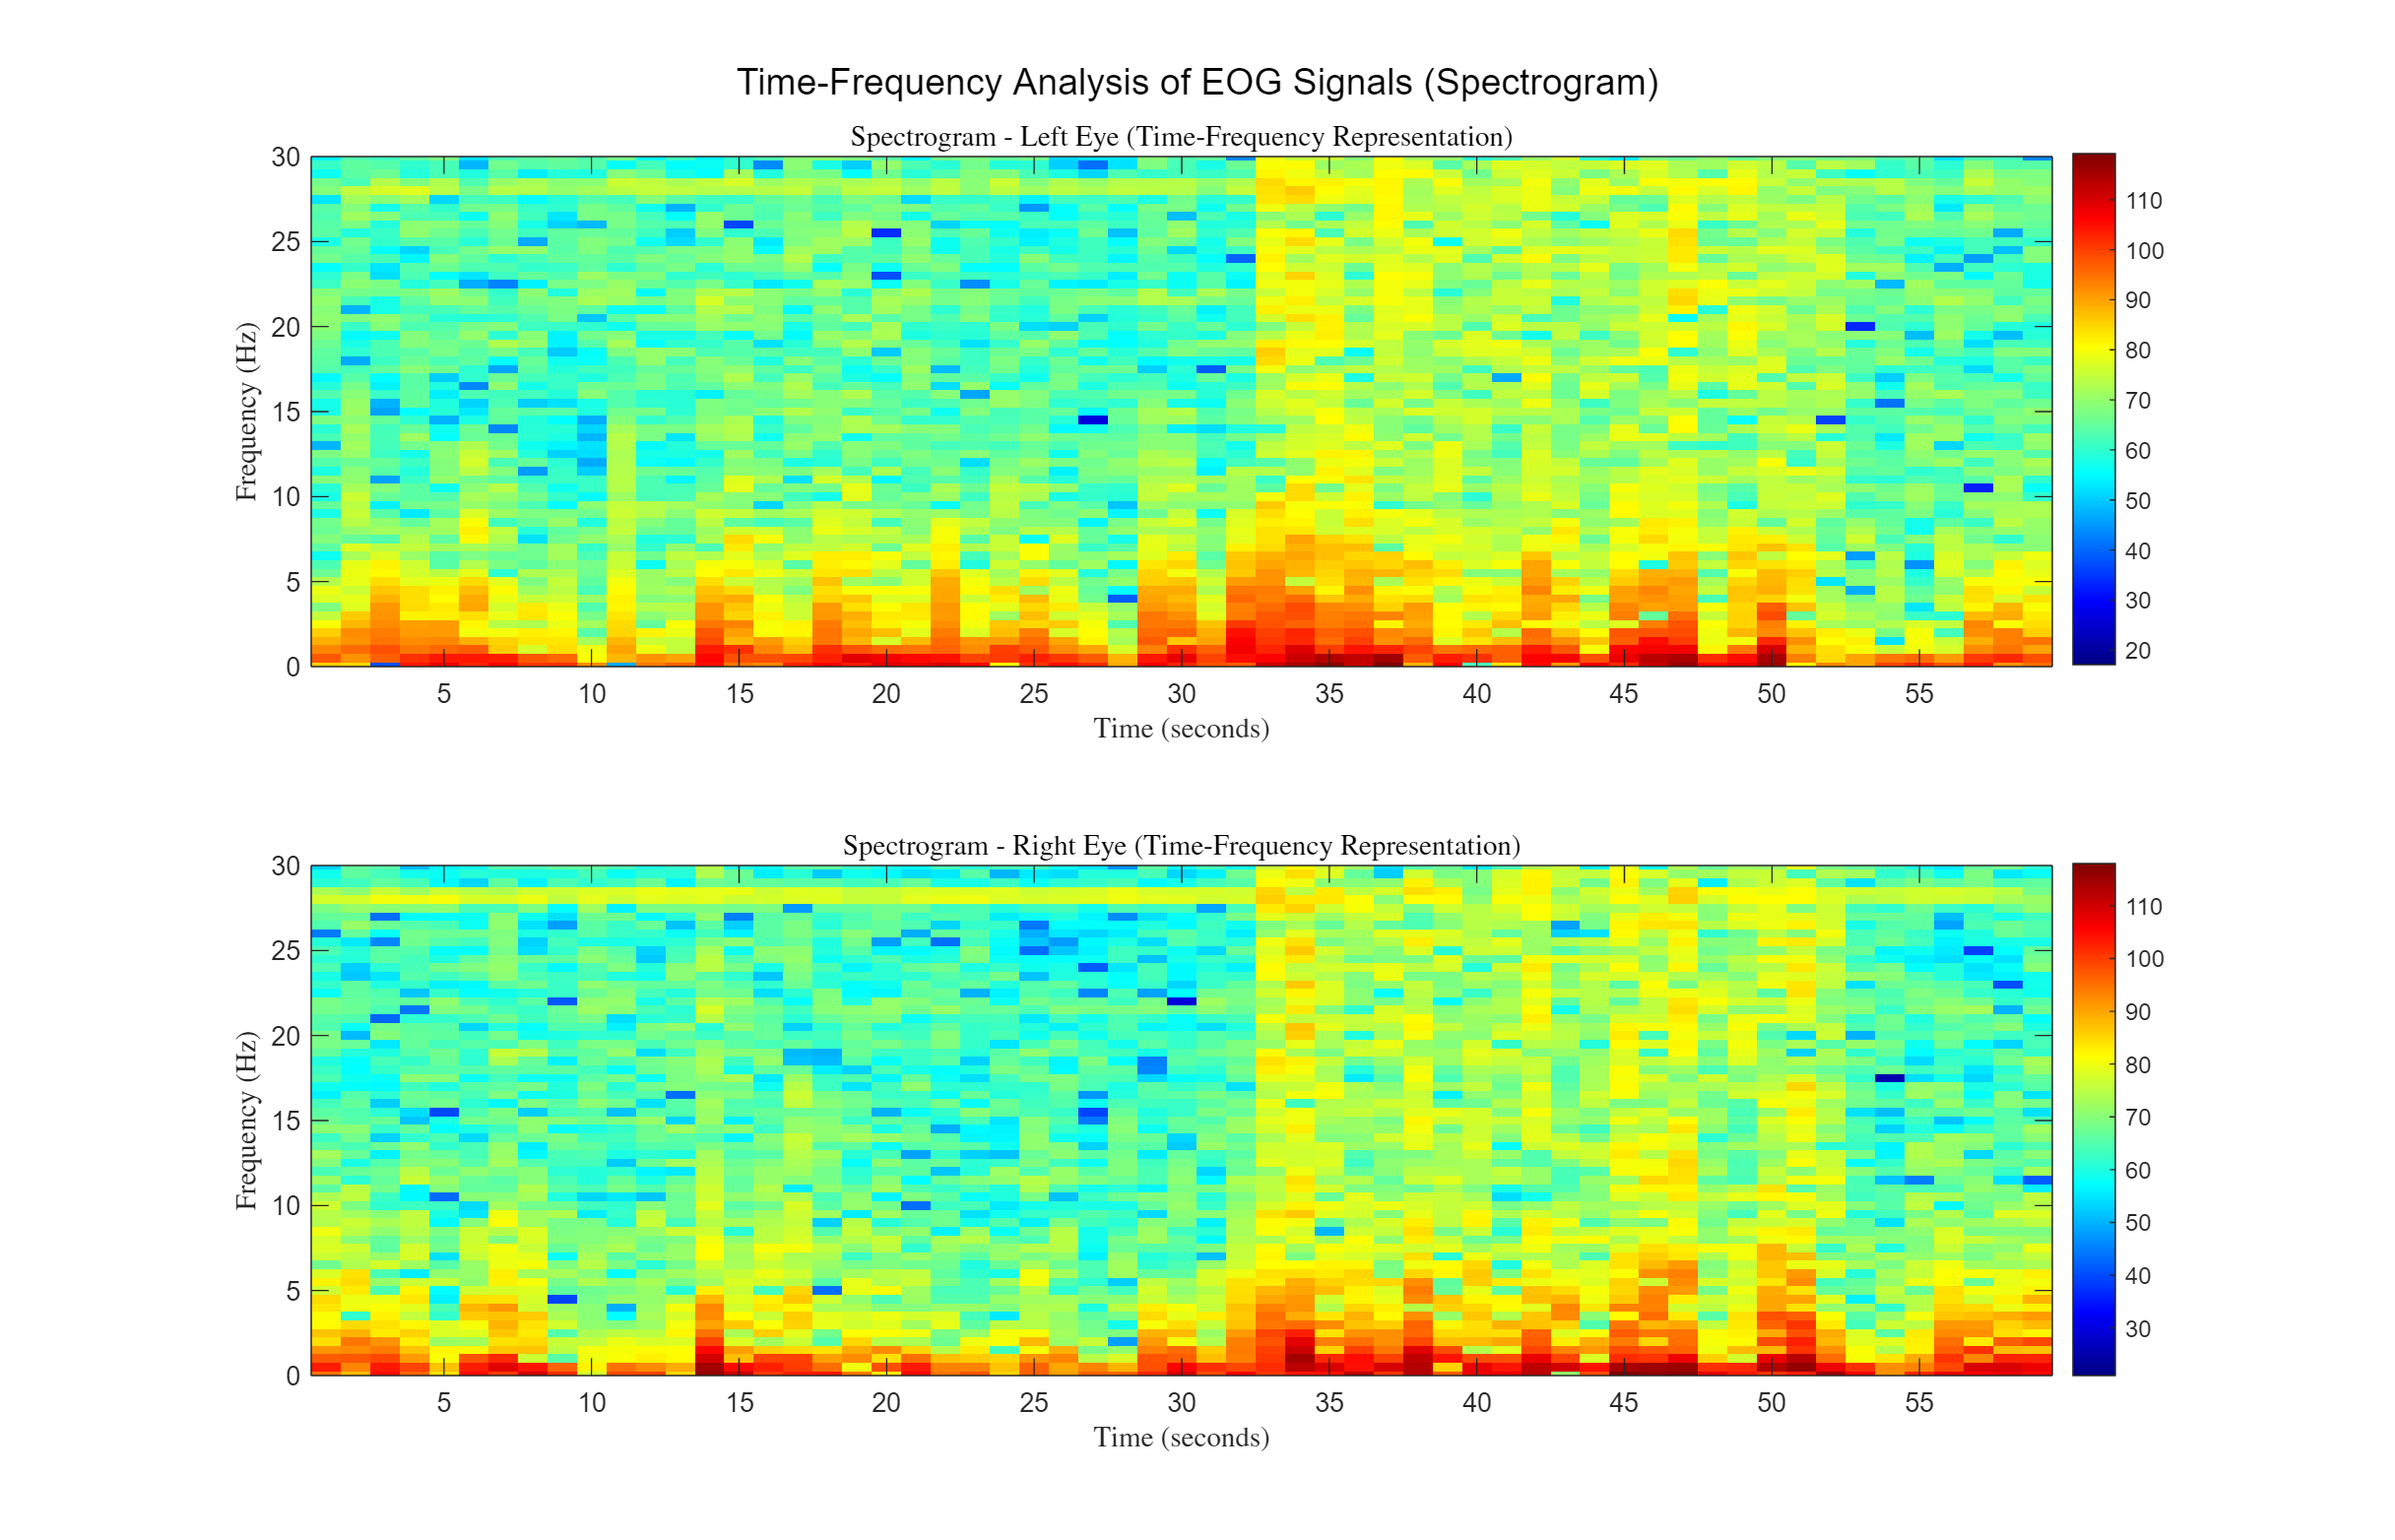

%% Spectrogram for both eyes
figure('Position', [100, 100, 1400, 900]);

window_length = 256;  
noverlap = 128;       
nfft = 256;           
window = hamming(window_length);

subplot(2,1,1);
[S_left, F_left, T_left] = spectrogram(eog_left, window, noverlap, nfft, fs, 'yaxis');
imagesc(T_left, F_left, 20*log10(abs(S_left) + eps));
axis xy;
xlabel('Time (seconds)', 'Interpreter', 'latex');
ylabel('Frequency (Hz)', 'Interpreter', 'latex');
title('Spectrogram - Left Eye (Time-Frequency Representation)', 'Interpreter', 'latex');
colorbar;
ylim([0, 30]);  % EOG frequencies are typically below 30 Hz
colormap('jet');

% Right Eye Spectrogram
subplot(2,1,2);
[S_right, F_right, T_right] = spectrogram(eog_right, window, noverlap, nfft, fs, 'yaxis');
imagesc(T_right, F_right, 20*log10(abs(S_right) + eps));
axis xy;
xlabel('Time (seconds)', 'Interpreter', 'latex');
ylabel('Frequency (Hz)', 'Interpreter', 'latex');
title('Spectrogram - Right Eye (Time-Frequency Representation)', 'Interpreter', 'latex');
colorbar;
ylim([0, 30]);
colormap('jet');

sgtitle('Time-Frequency Analysis of EOG Signals (Spectrogram)', 'FontSize', 14);

Unrecognized function or variable 'fft_mag_right'.